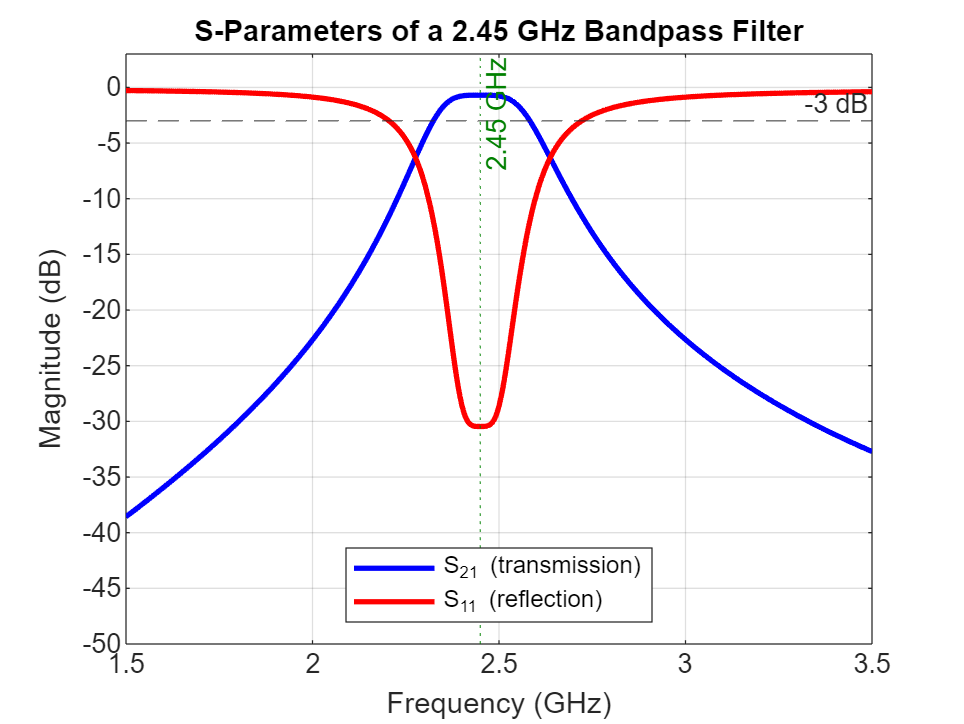

%% sparams_no_file.m
%  

%  The S-parameter data for a 2.45 GHz bandpass filter is generated
%  inside this script from a circuit model, so there is NOTHING to import.
%  Just open this file in MATLAB and press Run (F5).
%
%  Works in BASE MATLAB. If you also have the RF Toolbox, an optional
%  section at the bottom shows the one-line rfplot/smithplot versions.

clear; clc; close all;

%% 1. FREQUENCY SWEEP ----------------------------------------------------
f    = linspace(1.5e9, 3.5e9, 401).';   % 1.5 - 3.5 GHz, column vector
fGHz = f/1e9;
Z0   = 50;                               % reference impedance (ohm)

%% 2. GENERATE S-PARAMETERS FROM A FILTER MODEL --------------------------
%  A 2nd-order bandpass response centred at f0. This stands in for a real
%  measured device. S11 = reflection, S21 = transmission.
f0 = 2.45e9;          % centre frequency
BW = 0.20e9;          % ~200 MHz bandwidth
Q  = f0/BW;           % quality factor
IL = 0.7;             % in-band insertion loss (dB)

s   = 1i*(f/f0 - f0./f)*Q;        % normalised bandpass frequency variable
H   = 1 ./ (1 + s + 0.5*s.^2);    % 2-pole bandpass transfer function
S21 = H .* 10^(-IL/20);           % transmission, with a little loss
% Reflection: low in-band, high out-of-band. The +0.03 floor keeps the
% best-case match realistic (~ -30 dB) instead of a perfect zero.
S11 = ((1 - abs(H))*0.95 + 0.03) .* exp(-1i*2*angle(H));   % reflection
% (passive, reciprocal device: S12 = S21, S22 = S11 - not needed for plots)

% Convert to dB
S11_dB = 20*log10(abs(S11));      % related to Return Loss
S21_dB = 20*log10(abs(S21));      % related to Insertion Loss

%% 3. PLOT S11 & S21 MAGNITUDE (dB) --------------------------------------
figure('Name','S-Parameters','Color','w');
plot(fGHz, S21_dB, 'b', 'LineWidth', 2); hold on;
plot(fGHz, S11_dB, 'r', 'LineWidth', 2);
yline(-3, '--', '-3 dB');
xline(2.45, ':', '2.45 GHz', 'Color',[0 0.5 0]);
grid on;
xlabel('Frequency (GHz)'); ylabel('Magnitude (dB)');
title('S-Parameters of a 2.45 GHz Bandpass Filter');
legend('S_{21} (transmission)','S_{11} (reflection)','Location','south');
ylim([-50 3]);

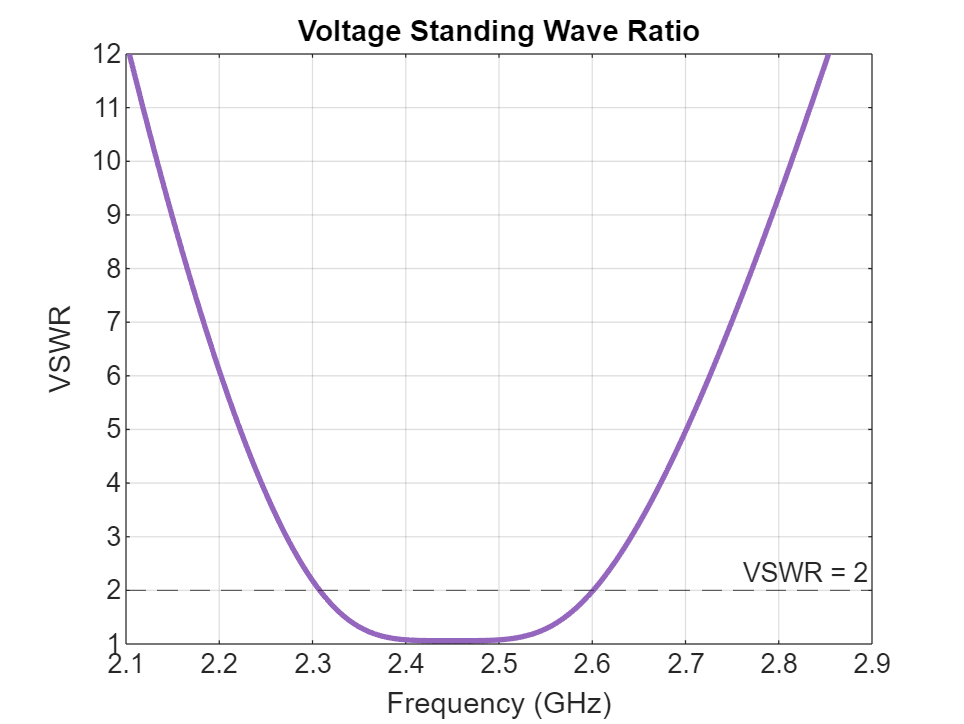


%% 4. PLOT VSWR ----------------------------------------------------------
%  VSWR expresses reflection as a standing-wave ratio. 1 = perfect match;
%  < 2 (return loss > 10 dB) is the usual "good enough" line.
vswr = (1 + abs(S11)) ./ (1 - abs(S11));
figure('Name','VSWR','Color','w');
plot(fGHz, vswr, 'Color',[0.58 0.40 0.74], 'LineWidth', 2);
yline(2, '--', 'VSWR = 2'); grid on;
xlabel('Frequency (GHz)'); ylabel('VSWR'); ylim([1 12]);
title('Voltage Standing Wave Ratio');

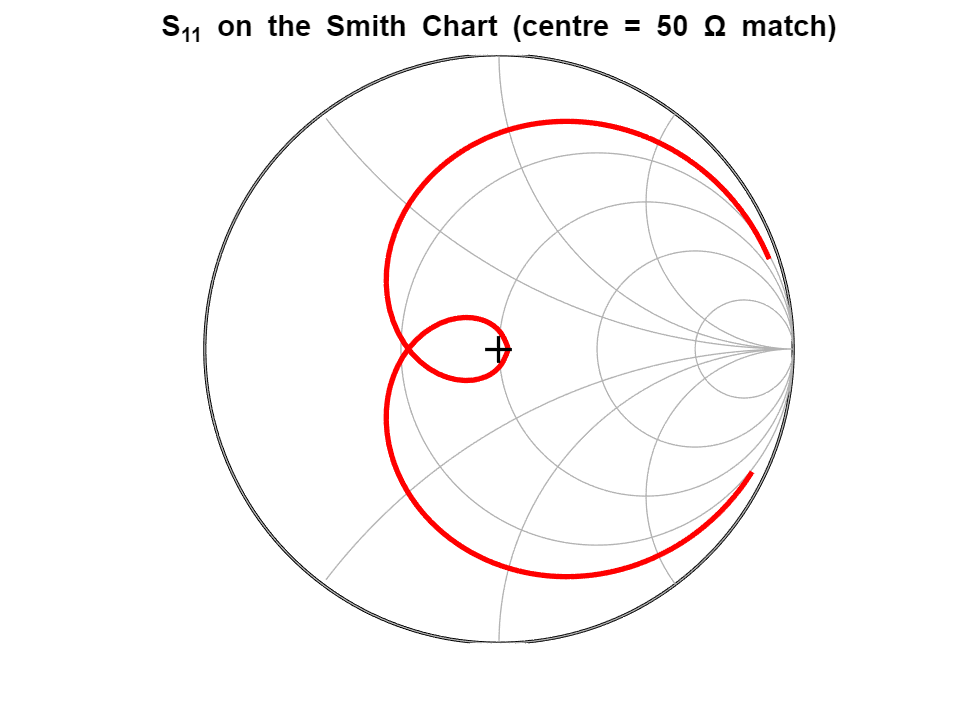


%% 5. SMITH CHART OF S11 (drawn manually, no toolbox needed) -------------
%  The Smith chart maps the reflection coefficient. Centre = perfect match
%  (Zin = 50 ohm). Right edge = open, left edge = short.
figure('Name','Smith Chart','Color','w'); hold on; axis equal off;
th = linspace(0,2*pi,200);
plot(cos(th), sin(th), 'k', 'LineWidth',1.2);          % unit circle (|Γ|=1)
% constant-resistance circles (r = 0, 0.5, 1, 2, 5)
for r = [0 0.5 1 2 5]
    cx = r/(1+r); rad = 1/(1+r);
    plot(cx+rad*cos(th), rad*sin(th), 'Color',[.7 .7 .7]);
end
% constant-reactance arcs (x = +-0.5, +-1, +-2)
for x = [0.5 1 2 -0.5 -1 -2]
    cy = 1/x; rad = abs(1/x);
    aa = linspace(0,2*pi,400);
    xx = 1 + rad*cos(aa); yy = cy + rad*sin(aa);
    in = (xx.^2 + yy.^2) <= 1.0001;       % keep only inside unit circle
    plot(xx(in), yy(in), 'Color',[.7 .7 .7]);
end
plot(real(S11), imag(S11), 'r', 'LineWidth',2);        % the S11 trace
plot(0,0,'k+','MarkerSize',10,'LineWidth',1.2);        % centre = 50 ohm
title('S_{11} on the Smith Chart (centre = 50 \Omega match)');


%% 6. KEY METRICS (printed to Command Window) ----------------------------
[s21max, kmax] = max(S21_dB);
fc    = fGHz(kmax);                       % centre frequency (S21 peak)
above = find(S21_dB >= s21max - 3);       % within 3 dB of the peak
fLo = fGHz(above(1)); fHi = fGHz(above(end));
BWm = (fHi - fLo)*1000;                    % bandwidth in MHz

fprintf('================ S-PARAMETER RESULTS ================\n');

================ S-PARAMETER RESULTS ================


fprintf(' Reference impedance       : %g ohm\n', Z0);

 Reference impedance       : 50 ohm


fprintf(' Centre frequency (S21 peak): %.3f GHz\n', fc);

 Centre frequency (S21 peak): 2.450 GHz


fprintf(' Insertion loss at centre  : %.2f dB\n', -s21max);

 Insertion loss at centre  : 0.70 dB


fprintf(' -3 dB passband            : %.3f - %.3f GHz (BW = %.0f MHz)\n', fLo, fHi, BWm);

 -3 dB passband            : 2.315 - 2.595 GHz (BW = 280 MHz)


fprintf(' Return loss at centre     : %.1f dB\n', -S11_dB(kmax));

 Return loss at centre     : 30.5 dB


fprintf(' VSWR at centre            : %.2f\n', vswr(kmax));

 VSWR at centre            : 1.06


fprintf('=====================================================\n');


%% 7. OPTIONAL: RF TOOLBOX VERSION ---------------------------------------
%  If you have the RF Toolbox, you can wrap the data in an sparameters
%  object and use the built-in plotting. Uncomment to use.
%
% Sdata          = zeros(2,2,numel(f));
% Sdata(1,1,:)   = S11;  Sdata(2,1,:) = S21;
% Sdata(1,2,:)   = S21;  Sdata(2,2,:) = S11;   % reciprocal
% S = sparameters(Sdata, f, Z0);               % built from memory, no file
% figure; rfplot(S,2,1);                       % S21 in dB
% figure; rfplot(S,1,1);                       % S11 in dB
% figure; smithplot(S,1,1);                    % S11 on a Smith chart